## Simulador SIR

Bruno Davidovitch Bertanha 20.01521-6

### Boas práticas

clear;
close all;
clc;

### Lendo e organizando os dados do modelo SIR

data = readtable("SIRpd.csv")

data = 1000×3 table
      S         I          R    
    ______    ______    ________

       499         1           0
    498.95    1.0407    0.010213
     498.9    1.0831    0.020841
    498.84    1.1273    0.031903
    498.78    1.1732    0.043415
    498.72     1.221    0.055396
    498.66    1.2707    0.067865
     498.6    1.3224    0.080842
    498.53    1.3762    0.094347
    498.46    1.4322      0.1084
    498.39    1.4905     0.12303
    498.31    1.5511     0.13825
    498.23    1.6142     0.15409
    498.15    1.6799     0.17057
    498.06    1.7482     0.18773
    497.98    1.8192     0.20558


data = table2array(data);

dias = 1:length(data);

 Criando ruído para os dados e os adicionando

Sd = data(1:end,1);
Id = data(1:end,2);
Rd = data(1:end,3);

Sdn = wgn(1000,1,0);
Idn = wgn(1000,1,0);
Rdn = wgn(1000,1,0);

Sd = Sd + Sdn;
Id = Id + Idn;
Rd = Rd + Rdn;  

### Visualizando os dados

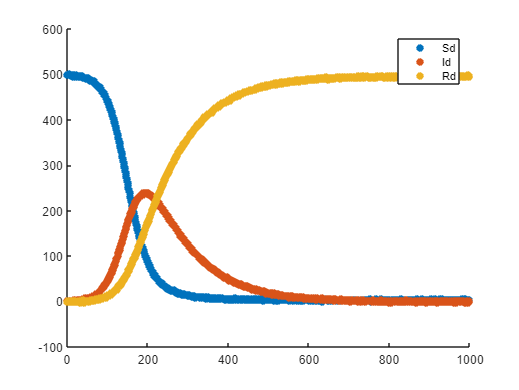

figure(1)

scatter(dias, Sd,'filled')
hold on
scatter(dias, Id,'filled')
hold on
scatter(dias, Rd,'filled')

legend("Sd", "Id", "Rd")

### Obtendo valores iniciais

%Tamanho da populção - N
N = 500;

%Valores iniciais 
global Beta r S0 I0 R0

I0 = 1;
R0 = 0;
S0 = N - I0;

y0 = [S0 I0 R0];

theta0 = [1e-4 1e-2];

### Otimizando Beta e r

theta_optimo = fminsearch(@(theta) erroSIR(theta, Sd, Id, Rd, dias), theta0)

theta_optimo =     0.0001    0.0100


### Visualizando Melhor Aproximação

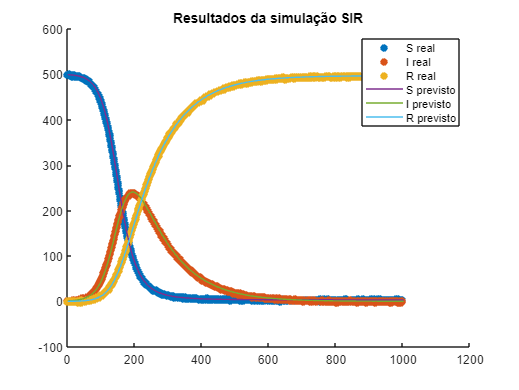

Beta = theta_optimo(1);
r = theta_optimo(2);

simOut = sim("simuladorSIR.slx");
St = simOut.logsout{1}.Values.Data;
It = simOut.logsout{2}.Values.Data;
Rt = simOut.logsout{3}.Values.Data;

t = 1:length(St);

%Plot dados SIR
figure(2)

scatter(dias, Sd,'filled')
hold on
scatter(dias, Id,'filled')
hold on
scatter(dias, Rd,'filled')

%Plot dados simulador

plot(t, St)
hold on
plot(t, It)
hold on
plot(t, Rt)

legend("S real", "I real", "R real", "S previsto", "I previsto", "R previsto")
title("Resultados da simulação SIR")

### Funções

function [erro] = erroSIR(theta, Sr, Ir, Rr, t)
    global Beta r
    Beta = theta(1);
    r = theta(2);

    simOut = sim("simuladorSIR.slx");
    Ss = simOut.logsout{1}.Values.Data;
    Is = simOut.logsout{2}.Values.Data;
    Rs = simOut.logsout{3}.Values.Data;
    % pegando os 1000 primeiros valores
    Ss = Ss(1:1000);
    Is = Is(1:1000);
    Rs = Rs(1:1000);

    % erro de cada variável de saída
    erro_S = sum((Sr - Ss).^2);
    erro_I = sum((Ir - Is).^2);
    erro_R = sum((Rr - Rs).^2);
    % soma dos erros
    erro = erro_S + erro_I + erro_R;
end
